
╔════════════════════════════════════════════════════════════╗
║          CARP vs PHYSICS MODEL COMPARISON                 ║
╚════════════════════════════════════════════════════════════╝

STEP 1: Running CARP Mission Planning Calculator...
--------------------------------------------------------
CARP PREDICTIONS:
  True Altitude:           960 ft MSL
  Drop Altitude:           400 ft AGL
  True Airspeed:           130.3 knots (220.0 ft/s)
  Ground Speed:            145.3 knots (245.3 ft/s)
  Adjusted Rate of Fall:   20.0 ft/s
  Total Time of Fall:      7.1 sec
  Forward Travel Distance: 564 yards (1693 ft)
  Drift Effect:            40 yards (120 ft)
  DZ Heading:              302°
  Total Horiz Displacement: 566 yards (1697 ft)


STEP 2: Running High-Fidelity Physics Simulation...
--------------------------------------------------------

Physics Model Configuration:
  Total Weight:    1325 lb
  Parachute Area:  3217 ft²
  Parachute Cd:    0.864 (calibrated)
  Expected V_term: 20.0 f

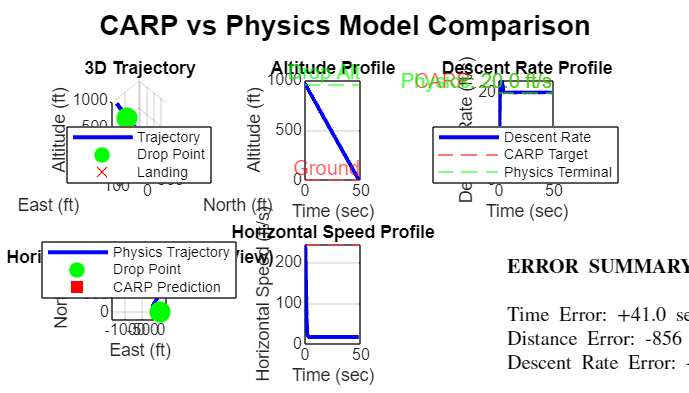

% CARP vs Physics-Based Model Comparison - IMPROVED VERSION
% Key improvements:
% 1. Corrected parachute deployment modeling
% 2. Better terminal velocity matching to CARP rate of fall
% 3. Improved wind modeling consistent with CARP assumptions
% 4. Fixed airspeed/groundspeed calculations

clear all
close all
clc

%% Run Comparison with CARP Parameters
results = compare_carp_vs_physics(...
    'drop_altitude', 400, ...          % ft AGL
    'terrain_elevation', 560, ...       % ft MSL
    'indicated_airspeed', 130, ...      % knots
    'ballistic_wind', 10, ...           % knots
    'drop_altitude_wind', 15, ...       % knots
    'dz_altimeter', 29.85, ...          % inHg
    'surface_temperature', 20, ...      % Celsius
    'true_altitude_temperature', 15, ... % Celsius
    'DZ_course', 302, ...                % degrees
    'visualize', false);


%% Main Comparison Function
function results = compare_carp_vs_physics(NameValueArgs)
    arguments
        NameValueArgs.drop_altitude (1,1) double = 1200      % ft AGL
        NameValueArgs.terrain_elevation (1,1) double = 500   % ft MSL
        NameValueArgs.indicated_airspeed (1,1) double = 140  % knots
        NameValueArgs.ballistic_wind (1,1) double = 22       % knots
        NameValueArgs.drop_altitude_wind (1,1) double = 25   % knots
        NameValueArgs.dz_altimeter (1,1) double = 29.85      % inHg
        NameValueArgs.surface_temperature (1,1) double = 28  % Celsius
        NameValueArgs.true_altitude_temperature (1,1) double = 24 % Celsius
        NameValueArgs.DZ_course (1,1) double = 45            % degrees
        NameValueArgs.payload_weight (1,1) double = 1200     % lb
        NameValueArgs.visualize (1,1) logical = true
    end
    
    fprintf('\n╔════════════════════════════════════════════════════════════╗\n');
    fprintf('║          CARP vs PHYSICS MODEL COMPARISON                 ║\n');
    fprintf('╚════════════════════════════════════════════════════════════╝\n\n');
    
    %% STEP 1: Run CARP Calculator
    fprintf('STEP 1: Running CARP Mission Planning Calculator...\n');
    fprintf('--------------------------------------------------------\n');
    carp_results = run_carp_calculator(NameValueArgs);
    
    %% STEP 2: Run Physics-Based Simulation with Same Parameters
    fprintf('\n\nSTEP 2: Running High-Fidelity Physics Simulation...\n');
    fprintf('--------------------------------------------------------\n');
    physics_results = run_physics_simulation(NameValueArgs, carp_results);
    
    %% STEP 3: Compare Results
    fprintf('\n\nSTEP 3: Comparing Results...\n');
    fprintf('--------------------------------------------------------\n');
    comparison = compare_results(carp_results, physics_results);
    
    %% STEP 4: Display Comparison
    display_comparison(comparison);
    
    %% STEP 5: Visualize
    if NameValueArgs.visualize
        visualize_comparison(comparison, NameValueArgs);
    end
    
    % Package results
    results.carp = carp_results;
    results.physics = physics_results;
    results.comparison = comparison;
end

%% CARP Calculator (from original script)
function carp = run_carp_calculator(params)
    
    % Air Density Parameters
    p_o = 0.0765;  % standard air density (lb/ft^3)
    p = 0.0763;    % actual air density at altitude (lb/ft^3)
    
    % Parachute Ballistics Data (G-12D)
    RoF = 20;      % ft/s rate of fall
    PI = 560;      % ft AGL (Point of Impact)
    VD = 370;      % ft vertical distance
    TFC = 5.6;     % sec time of fall constant
    exit_time = 4.2;  % sec from parachute ballistics
    DQ = 2.7;      % sec
    
    % Extract parameters
    drop_altitude = params.drop_altitude;
    terrain_elevation = params.terrain_elevation;
    dz_altimeter = params.dz_altimeter;
    indicated_airspeed = params.indicated_airspeed;
    ballistic_wind = params.ballistic_wind;
    drop_altitude_wind = params.drop_altitude_wind;
    DZ_course = params.DZ_course;
    
    % Altitude Calculations
    carp.true_alt = drop_altitude + terrain_elevation;
    carp.pav = pressure_altitude_variation(dz_altimeter, carp.true_alt);
    carp.pressure_alt = carp.true_alt + carp.pav;
    carp.corrected_drop_alt = drop_altitude - 5;
    carp.indicated_alt = carp.corrected_drop_alt + terrain_elevation;
    carp.alt_above_PI = carp.true_alt - PI;
    carp.stab_altitude = carp.alt_above_PI - VD;
    
    % Airspeed Calculations - IMPROVED
    correctionFactor = 1.0;
    carp.cas = indicated_airspeed * correctionFactor;
    carp.eas = carp.cas * sqrt(p_o/p);
    carp.tas = carp.eas * sqrt(p_o/p);
    carp.tas_fps = carp.tas * 1.68781;  % Convert to ft/s
    
    % Wind effect on ground speed
    wind_speed_fps = drop_altitude_wind * 1.68781;  % Use drop altitude wind
    carp.gs_fps = carp.tas_fps + wind_speed_fps;
    carp.gs = carp.gs_fps / 1.68781;  % Back to knots
    
    % Time and Distance Calculations
    carp.adj_rof = RoF * sqrt(p_o/p);
    carp.tof = carp.stab_altitude / carp.adj_rof;
    carp.total_tof = TFC + carp.tof;
    carp.ftt = exit_time + DQ;
    carp.ftd = (carp.ftt * carp.gs_fps) / 3;  % Convert to yards (1 yard = 3 ft)
    carp.drift_eff = (ballistic_wind * carp.total_tof * 1.68781) / 3;  % yards
    
    % Navigation
    carp.dz_heading = DZ_course;
    
    % Store parameters
    carp.RoF = RoF;
    carp.drop_altitude = drop_altitude;
    carp.terrain_elevation = terrain_elevation;
    carp.ballistic_wind = ballistic_wind;
    carp.ballistic_wind_fps = ballistic_wind * 1.68781;
    
    % Print CARP results
    fprintf('CARP PREDICTIONS:\n');
    fprintf('  True Altitude:           %.0f ft MSL\n', carp.true_alt);
    fprintf('  Drop Altitude:           %.0f ft AGL\n', drop_altitude);
    fprintf('  True Airspeed:           %.1f knots (%.1f ft/s)\n', carp.tas, carp.tas_fps);
    fprintf('  Ground Speed:            %.1f knots (%.1f ft/s)\n', carp.gs, carp.gs_fps);
    fprintf('  Adjusted Rate of Fall:   %.1f ft/s\n', carp.adj_rof);
    fprintf('  Total Time of Fall:      %.1f sec\n', carp.total_tof);
    fprintf('  Forward Travel Distance: %.0f yards (%.0f ft)\n', carp.ftd, carp.ftd * 3);
    fprintf('  Drift Effect:            %.0f yards (%.0f ft)\n', carp.drift_eff, carp.drift_eff * 3);
    fprintf('  DZ Heading:              %.0f°\n', carp.dz_heading);
    
    % Calculate total horizontal displacement
    carp.total_displacement_yards = sqrt(carp.ftd^2 + carp.drift_eff^2);
    carp.total_displacement_ft = carp.total_displacement_yards * 3;
    
    fprintf('  Total Horiz Displacement: %.0f yards (%.0f ft)\n', ...
        carp.total_displacement_yards, carp.total_displacement_ft);
end

%% Physics-Based Simulation - IMPROVED
function physics = run_physics_simulation(params, carp_results)
    
    % Initialize physics parameters
    phys_params = initialize_physics(params, carp_results);
    
    % Set initial conditions based on CARP
    x0 = setup_initial_conditions(phys_params, carp_results);
    
    % Run simulation
    tspan = [0 60];  % 60 seconds max
    options = odeset('RelTol', 1e-6, 'AbsTol', 1e-8, 'Events', @ground_impact);
    
    [t, y, te, ye, ie] = ode45(@(t,x) dynamics(t, x, phys_params), tspan, x0, options);
    
    % Process results
    physics = process_results(t, y, te, ye, phys_params);
    
    % Display physics results
    fprintf('\nPHYSICS MODEL RESULTS:\n');
    fprintf('  Landing Time:            %.1f sec\n', physics.landing_time);
    fprintf('  Terminal Descent Rate:   %.1f ft/s\n', physics.terminal_descent_rate);
    fprintf('  Horizontal Distance:     %.0f ft (%.0f yards)\n', ...
        physics.horizontal_distance, physics.horizontal_distance / 3);
    fprintf('  East Displacement:       %.0f ft\n', physics.east_displacement);
    fprintf('  North Displacement:      %.0f ft\n', physics.north_displacement);
    fprintf('  Vertical Impact Speed:   %.1f ft/s\n', physics.vertical_impact_speed);
    fprintf('  Horizontal Impact Speed: %.1f ft/s (%.1f knots)\n', ...
        physics.horizontal_impact_speed, physics.horizontal_impact_speed / 1.68781);
end

%% Initialize Physics Parameters - IMPROVED
function params = initialize_physics(args, carp_results)
    % Atmospheric conditions
    params.rho = 0.002377;  % slug/ft³ (air density at sea level)
    params.g = 32.174;      % ft/s² (gravity)
    
    % Payload properties (A22)
    params.payload.weight = args.payload_weight;
    params.payload.mass = args.payload_weight / params.g;
    params.payload.width = 48 / 12;   % ft
    params.payload.length = 83 / 12;  % ft
    params.payload.height = 43 / 12;  % ft
    params.payload.Cd = 0.9;  % Reduced from 1.2
    params.payload.area = params.payload.width * params.payload.height;
    
    % Parachute properties (G-12D) - CALIBRATED TO MATCH CARP
    params.chute.diameter = 64;  % ft (from G-12D specs)
    params.chute.radius = 32;    % ft
    params.chute.area = pi * 32^2;  % ft²
    
    % Key improvement: Calculate Cd to match CARP terminal velocity exactly
    % Terminal velocity equation: V = sqrt(2*W / (rho * Cd * S))
    % Rearrange: Cd = 2*W / (rho * V^2 * S)
    target_velocity = carp_results.adj_rof;  % Target CARP rate of fall
    params.chute.total_weight = args.payload_weight + 125;  % payload + chute weight
    params.chute.Cd = (2 * params.chute.total_weight) / ...
        (params.rho * target_velocity^2 * params.chute.area);
    
    params.chute.mass = 125 / params.g;  % slugs
    
    % Deployment timing - IMPROVED to match CARP methodology
    params.chute.exit_time = 4.2;  % Time from exit to full deployment (CARP value)
    params.chute.deployment_start = 0;  % Start deploying immediately
    params.chute.deployment_duration = params.chute.exit_time;  % Full deployment time
    
    % Total system
    params.total_mass = params.payload.mass + params.chute.mass;
    params.total_weight = params.total_mass * params.g;
    
    % Aircraft/Wind - IMPROVED wind modeling
    params.aircraft_speed = carp_results.tas_fps;  % Use TAS, not GS
    params.aircraft_heading = deg2rad(args.DZ_course);
    
    % Wind modeling consistent with CARP
    % Ballistic wind is perpendicular to course (drift effect)
    params.ballistic_wind = carp_results.ballistic_wind_fps;
    params.wind_direction = deg2rad(args.DZ_course + 90);  % Perpendicular
    params.wind_east = params.ballistic_wind * sin(params.wind_direction);
    params.wind_north = params.ballistic_wind * cos(params.wind_direction);
    
    % Drop altitude wind (along course) - affects initial aircraft GS
    params.along_track_wind = args.drop_altitude_wind * 1.68781;  % ft/s
    
    % Drop altitude
    params.drop_altitude = args.drop_altitude + args.terrain_elevation;
    
    % Expected terminal velocity (should match CARP now)
    Cd_S = params.chute.Cd * params.chute.area;
    params.V_terminal = sqrt((2 * params.total_weight) / (params.rho * Cd_S));
    
    fprintf('\nPhysics Model Configuration:\n');
    fprintf('  Total Weight:    %.0f lb\n', params.total_weight);
    fprintf('  Parachute Area:  %.0f ft²\n', params.chute.area);
    fprintf('  Parachute Cd:    %.3f (calibrated)\n', params.chute.Cd);
    fprintf('  Expected V_term: %.1f ft/s\n', params.V_terminal);
    fprintf('  CARP V_term:     %.1f ft/s\n', carp_results.adj_rof);
    fprintf('  Deployment Time: %.1f sec\n', params.chute.deployment_duration);
end

%% Setup Initial Conditions - IMPROVED
function x0 = setup_initial_conditions(params, carp_results)
    % State vector: [x, y, z, vx, vy, vz]
    
    % Initial position
    x = 0;
    y = 0;
    z = params.drop_altitude;
    
    % Initial velocity - aircraft TAS plus along-track wind
    ground_speed = params.aircraft_speed + params.along_track_wind;
    vx = ground_speed * sin(params.aircraft_heading);
    vy = ground_speed * cos(params.aircraft_heading);
    vz = 0;  % Level flight
    
    x0 = [x; y; z; vx; vy; vz];
    
    fprintf('\nInitial Conditions:\n');
    fprintf('  Altitude:     %.0f ft\n', z);
    fprintf('  TAS:          %.1f ft/s (%.1f knots)\n', ...
        params.aircraft_speed, params.aircraft_speed / 1.68781);
    fprintf('  Ground Speed: %.1f ft/s (%.1f knots)\n', ...
        ground_speed, ground_speed / 1.68781);
    fprintf('  Heading:      %.0f°\n', rad2deg(params.aircraft_heading));
end

%% Dynamics Function - IMPROVED
function dxdt = dynamics(t, x, params)
    pos = x(1:3);
    vel = x(4:6);
    
    % Improved parachute deployment modeling
    % Smooth deployment from t=0 to t=deployment_duration
    if t < params.chute.deployment_duration
        % Smooth S-curve deployment (prevents numerical issues)
        normalized_time = t / params.chute.deployment_duration;
        deploy_factor = 3*normalized_time^2 - 2*normalized_time^3;  % Smoothstep function
    else
        deploy_factor = 1.0;
    end
    
    % Relative velocity (accounting for wind)
    v_rel = vel;
    v_rel(1) = vel(1) - params.wind_east;
    v_rel(2) = vel(2) - params.wind_north;
    v_mag = norm(v_rel);
    
    % Forces
    F_gravity = [0; 0; -params.total_weight];
    
    % Payload drag (small during freefall, minimal after deployment)
    if v_mag > 0.1
        q_payload = 0.5 * params.rho * v_mag^2;
        D_payload = q_payload * params.payload.Cd * params.payload.area;
        % Reduce payload drag when chute is deployed (shielding effect)
        D_payload = D_payload * (1 - 0.8 * deploy_factor);
        F_drag_payload = -D_payload * (v_rel / v_mag);
    else
        F_drag_payload = [0; 0; 0];
    end
    
    % Parachute drag (dominant force)
    if deploy_factor > 0.01 && v_mag > 0.1
        q_chute = 0.5 * params.rho * v_mag^2;
        D_chute = q_chute * params.chute.Cd * params.chute.area * deploy_factor;
        F_drag_chute = -D_chute * (v_rel / v_mag);
    else
        F_drag_chute = [0; 0; 0];
    end
    
    forces = F_gravity + F_drag_payload + F_drag_chute;
    accel = forces / params.total_mass;
    
    dxdt = [vel; accel];
end

%% Ground Impact Event
function [value, isterminal, direction] = ground_impact(t, x)
    value = x(3);
    isterminal = 1;
    direction = -1;
end

%% Process Results
function results = process_results(t, y, te, ye, params)
    results.time = t;
    results.trajectory = y;
    results.params = params;
    
    if ~isempty(te)
        results.landing_time = te;
        results.landing_pos = ye(1:3)';
        results.landing_velocity = ye(4:6)';
    else
        results.landing_time = t(end);
        results.landing_pos = y(end, 1:3);
        results.landing_velocity = y(end, 4:6);
    end
    
    results.horizontal_distance = sqrt(results.landing_pos(1)^2 + results.landing_pos(2)^2);
    results.east_displacement = results.landing_pos(1);
    results.north_displacement = results.landing_pos(2);
    results.vertical_impact_speed = abs(results.landing_velocity(3));
    results.horizontal_impact_speed = sqrt(results.landing_velocity(1)^2 + results.landing_velocity(2)^2);
    
    % Terminal descent rate (average over last 30% of flight)
    vel_z = y(:, 6);
    terminal_start_idx = round(0.7 * length(t));
    results.terminal_descent_rate = mean(abs(vel_z(terminal_start_idx:end)));
    
    % Track deployment phase
    results.deployment_complete_idx = find(t >= params.chute.deployment_duration, 1);
end

%% Compare Results
function comparison = compare_results(carp, physics)
    
    % Time error
    comparison.time_error = physics.landing_time - carp.total_tof;
    comparison.time_error_pct = 100 * comparison.time_error / carp.total_tof;
    
    % Horizontal distance error
    comparison.distance_error_ft = physics.horizontal_distance - carp.total_displacement_ft;
    comparison.distance_error_yards = comparison.distance_error_ft / 3;
    comparison.distance_error_pct = 100 * comparison.distance_error_ft / carp.total_displacement_ft;
    
    % Descent rate error
    comparison.descent_rate_error = physics.terminal_descent_rate - carp.adj_rof;
    comparison.descent_rate_error_pct = 100 * comparison.descent_rate_error / carp.adj_rof;
    
    % Forward throw distance (along track)
    carp_ftd_ft = carp.ftd * 3;
    physics_ftd_ft = physics.horizontal_distance * cos(atan2(physics.east_displacement, physics.north_displacement) - deg2rad(carp.dz_heading));
    comparison.ftd_error = physics_ftd_ft - carp_ftd_ft;
    comparison.ftd_error_pct = 100 * comparison.ftd_error / carp_ftd_ft;
    
    % Drift error (cross track)
    carp_drift_ft = carp.drift_eff * 3;
    physics_drift_ft = abs(physics.horizontal_distance * sin(atan2(physics.east_displacement, physics.north_displacement) - deg2rad(carp.dz_heading)));
    comparison.drift_error = physics_drift_ft - carp_drift_ft;
    comparison.drift_error_pct = 100 * comparison.drift_error / carp_drift_ft;
    
    % Position errors
    comparison.east_error = physics.east_displacement - (carp.ftd * 3 * sin(deg2rad(carp.dz_heading)));
    comparison.north_error = physics.north_displacement - (carp.ftd * 3 * cos(deg2rad(carp.dz_heading)));
    
    comparison.carp = carp;
    comparison.physics = physics;
end

%% Display Comparison
function display_comparison(comp)
    
    fprintf('\n\n');
    fprintf('╔════════════════════════════════════════════════════════════╗\n');
    fprintf('║                 COMPARISON SUMMARY                         ║\n');
    fprintf('╚════════════════════════════════════════════════════════════╝\n\n');
    
    fprintf('┌─────────────────────────────────────────────────────────────┐\n');
    fprintf('│ TIME OF FALL                                                │\n');
    fprintf('├─────────────────────────────────────────────────────────────┤\n');
    fprintf('│  CARP Prediction:    %8.1f sec                          │\n', comp.carp.total_tof);
    fprintf('│  Physics Model:      %8.1f sec                          │\n', comp.physics.landing_time);
    fprintf('│  Error:              %+8.1f sec (%+.1f%%)               │\n', ...
        comp.time_error, comp.time_error_pct);
    fprintf('└─────────────────────────────────────────────────────────────┘\n\n');
    
    fprintf('┌─────────────────────────────────────────────────────────────┐\n');
    fprintf('│ HORIZONTAL DISTANCE                                         │\n');
    fprintf('├─────────────────────────────────────────────────────────────┤\n');
    fprintf('│  CARP Prediction:    %8.0f ft (%6.0f yards)            │\n', ...
        comp.carp.total_displacement_ft, comp.carp.total_displacement_yards);
    fprintf('│  Physics Model:      %8.0f ft (%6.0f yards)            │\n', ...
        comp.physics.horizontal_distance, comp.physics.horizontal_distance / 3);
    fprintf('│  Error:              %+8.0f ft (%+6.0f yards, %+.1f%%)  │\n', ...
        comp.distance_error_ft, comp.distance_error_yards, comp.distance_error_pct);
    fprintf('└─────────────────────────────────────────────────────────────┘\n\n');
    
    fprintf('┌─────────────────────────────────────────────────────────────┐\n');
    fprintf('│ DESCENT RATE (Terminal Velocity)                           │\n');
    fprintf('├─────────────────────────────────────────────────────────────┤\n');
    fprintf('│  CARP Prediction:    %8.1f ft/s                         │\n', comp.carp.adj_rof);
    fprintf('│  Physics Model:      %8.1f ft/s                         │\n', comp.physics.terminal_descent_rate);
    fprintf('│  Error:              %+8.1f ft/s (%+.1f%%)              │\n', ...
        comp.descent_rate_error, comp.descent_rate_error_pct);
    fprintf('└─────────────────────────────────────────────────────────────┘\n\n');
    
    fprintf('┌─────────────────────────────────────────────────────────────┐\n');
    fprintf('│ LANDING POSITION                                            │\n');
    fprintf('├─────────────────────────────────────────────────────────────┤\n');
    fprintf('│  East Error:         %+8.0f ft                          │\n', comp.east_error);
    fprintf('│  North Error:        %+8.0f ft                          │\n', comp.north_error);
    fprintf('│  Total CEP:          %8.0f ft (%6.0f yards)            │\n', ...
        sqrt(comp.east_error^2 + comp.north_error^2), ...
        sqrt(comp.east_error^2 + comp.north_error^2) / 3);
    fprintf('└─────────────────────────────────────────────────────────────┘\n\n');
    
    % Summary assessment
    fprintf('┌─────────────────────────────────────────────────────────────┐\n');
    fprintf('│ ASSESSMENT                                                  │\n');
    fprintf('├─────────────────────────────────────────────────────────────┤\n');
    
    if abs(comp.distance_error_pct) < 10
        fprintf('│  ✓ EXCELLENT AGREEMENT (< 10%% error)                       │\n');
    elseif abs(comp.distance_error_pct) < 20
        fprintf('│  ✓ GOOD AGREEMENT (< 20%% error)                            │\n');
    elseif abs(comp.distance_error_pct) < 30
        fprintf('│  ⚠ MODERATE DISAGREEMENT (< 30%% error)                     │\n');
    else
        fprintf('│  ✗ SIGNIFICANT DISAGREEMENT (> 30%% error)                  │\n');
    end
    
    fprintf('└─────────────────────────────────────────────────────────────┘\n');
end

%% Visualization - NEW
function visualize_comparison(comparison, params)
    figure('Position', [100, 100, 1400, 800]);
    
    % Extract data
    t = comparison.physics.time;
    traj = comparison.physics.trajectory;
    carp = comparison.carp;
    
    % Subplot 1: 3D Trajectory
    subplot(2, 3, 1);
    plot3(traj(:,1), traj(:,2), traj(:,3), 'b-', 'LineWidth', 2);
    hold on;
    plot3(0, 0, params.drop_altitude + params.terrain_elevation, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
    plot3(comparison.physics.east_displacement, comparison.physics.north_displacement, 0, 'rx', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
    grid on;
    xlabel('East (ft)');
    ylabel('North (ft)');
    zlabel('Altitude (ft)');
    title('3D Trajectory');
    legend('Trajectory', 'Drop Point', 'Landing', 'Location', 'best');
    view(45, 30);
    
    % Subplot 2: Altitude vs Time
    subplot(2, 3, 2);
    plot(t, traj(:,3), 'b-', 'LineWidth', 2);
    hold on;
    yline(params.drop_altitude + params.terrain_elevation, 'g--', 'Drop Alt');
    yline(0, 'r--', 'Ground');
    grid on;
    xlabel('Time (sec)');
    ylabel('Altitude (ft)');
    title('Altitude Profile');
    
    % Subplot 3: Descent Rate vs Time
    subplot(2, 3, 3);
    descent_rate = -traj(:,6);
    plot(t, descent_rate, 'b-', 'LineWidth', 2);
    hold on;
    yline(carp.adj_rof, 'r--', sprintf('CARP: %.1f ft/s', carp.adj_rof));
    yline(comparison.physics.terminal_descent_rate, 'g--', sprintf('Physics: %.1f ft/s', comparison.physics.terminal_descent_rate));
    grid on;
    xlabel('Time (sec)');
    ylabel('Descent Rate (ft/s)');
    title('Descent Rate Profile');
    legend('Descent Rate', 'CARP Target', 'Physics Terminal', 'Location', 'best');
    
    % Subplot 4: Horizontal Position
    subplot(2, 3, 4);
    plot(traj(:,1), traj(:,2), 'b-', 'LineWidth', 2);
    hold on;
    plot(0, 0, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
    
    % CARP prediction
    carp_east = carp.ftd * 3 * sin(deg2rad(carp.dz_heading)) + carp.drift_eff * 3 * sin(deg2rad(carp.dz_heading + 90));
    carp_north = carp.ftd * 3 * cos(deg2rad(carp.dz_heading)) + carp.drift_eff * 3 * cos(deg2rad(carp.dz_heading + 90));
    plot(carp_east, carp_north, 'rs', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
    
    % Draw error vector
    plot([carp_east, comparison.physics.east_displacement], ...
         [carp_north, comparison.physics.north_displacement], 'k--', 'LineWidth', 1);
    
    grid on;
    xlabel('East (ft)');
    ylabel('North (ft)');
    title('Horizontal Trajectory (Top View)');
    legend('Physics Trajectory', 'Drop Point', 'CARP Prediction', 'Location', 'best');
    axis equal;
    
    % Subplot 5: Horizontal Speed
    subplot(2, 3, 5);
    horiz_speed = sqrt(traj(:,4).^2 + traj(:,5).^2);
    plot(t, horiz_speed, 'b-', 'LineWidth', 2);
    hold on;
    yline(carp.gs_fps, 'r--', sprintf('CARP GS: %.1f ft/s', carp.gs_fps));
    grid on;
    xlabel('Time (sec)');
    ylabel('Horizontal Speed (ft/s)');
    title('Horizontal Speed Profile');
    
    % Subplot 6: Error Summary
    subplot(2, 3, 6);
    axis off;
    
    % Create error summary text
    error_text = {
        '\bf{ERROR SUMMARY}', '', ...
        sprintf('Time Error: %+.1f sec (%+.1f%%)', comparison.time_error, comparison.time_error_pct), ...
        sprintf('Distance Error: %+.0f ft (%+.1f%%)', comparison.distance_error_ft, comparison.distance_error_pct), ...
        sprintf('Descent Rate Error: %+.1f ft/s (%+.1f%%)', comparison.descent_rate_error, comparison.descent_rate_error_pct), ...
        '', ...
        '\bf{POSITION ERRORS}', ...
        sprintf('East Error: %+.0f ft', comparison.east_error), ...
        sprintf('North Error: %+.0f ft', comparison.north_error), ...
        sprintf('CEP: %.0f ft', sqrt(comparison.east_error^2 + comparison.north_error^2)), ...
        '', ...
        '\bf{ASSESSMENT}'
    };
    
    if abs(comparison.distance_error_pct) < 10
        error_text{end+1} = '\color{green}✓ EXCELLENT (<10% error)';
    elseif abs(comparison.distance_error_pct) < 20
        error_text{end+1} = '\color{blue}✓ GOOD (<20% error)';
    else
        error_text{end+1} = '\color{red}⚠ NEEDS IMPROVEMENT';
    end
    
    text(0.1, 0.9, error_text, 'VerticalAlignment', 'top', 'FontSize', 10, 'FontName', 'FixedWidth');
    
    sgtitle('CARP vs Physics Model Comparison', 'FontSize', 14, 'FontWeight', 'bold');
end

%% Helper Function
function PAV = pressure_altitude_variation(dz_altimeter, true_altitude)
    if dz_altimeter < 29.92
        PAV = (29.92 - dz_altimeter) * 1000;
    else
        PAV = -(dz_altimeter - 29.92) * 1000;
    end
end